# Example: Fitting the Uniform shear model

## Introduction

The uniform shear model [1] is fitted to two different datasets:

-  The spectral densities collected during the Great Belt experiment and displayed in Mann [1]. the fit should give the following parameters close to: $$\alpha \epsilon^{3/2} = 0.11$$ m$$^{4/3}$s$$^{-2}$ $, $$\Gamma = 3.2$$, and $$L = 61$$ m. 

- the spectral model proposed by Kaimal et al. [2] for a mean wind speed of 40 ms$$^{-1}$$ at a height of 40 m above the ground. Following Mann [3], the fit should give the following parameters close to: $$\alpha \epsilon^{3/2} = 0.86$$ m$$^{4/3}$s$$^{-2}$ $, $$\Gamma = 3.9$$, and $$L = 24$$ m. 

The function **fitMann** implements the fitting algorithm on a slightly different way from the one used by Mann [1]. The present Matlab implementation was applied in Ref. [4] and simultaneously fit the three parameters. However, the function** fitMann** can use the parameter $$\alpha \epsilon^{3/2}$$ as an optional input, and the fit is conducted only for two unknown variables: $$\Gamma$$ and $$L$$.

### References

[1] Mann, J. (1994). The spatial structure of neutral atmospheric surface-layer turbulence. *Journal of fluid mechanics*, *273*, 141-168.

[2] Kaimal, J. C., Wyngaard, J. C. J., Izumi, Y., & Coté, O. R. (1972). Spectral characteristics of surface‐layer turbulence. *Quarterly Journal of the Royal Meteorological Society*, *98*(417), 563-589.

[3] Mann, J. (1998). Wind field simulation. *Probabilistic engineering mechanics*, *13*(4), 269-282.

[4] Cheynet, E. (2019). Influence of the Measurement Height on the Vertical Coherence of Natural Wind. In *Conference of the Italian Association for Wind Engineering* (pp. 207-221). Springer, Cham

## Fitting to the data from the great Belt experiment

### Initialisation

No blocking by the surface is modelled here. Therefore, the imaginary part of the cross power spectral density (CPSD) between the along-wind and vertical wind component is zero. 

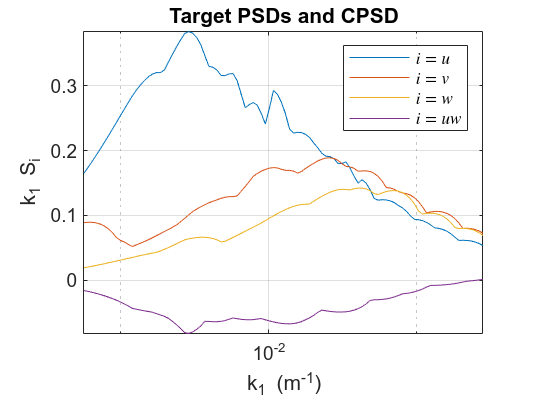

clearvars;close all;clc;
meanU = 22.3; % Mean wind speed (m/s)
z = 70; % altitude (m) 
load('greatBeltData.mat','k1','Su','Sv','Sw','Suw')
N1 = numel(k1);

clf;close all;
figure
semilogx(k1,k1.*Su ,k1,k1.*Sv ,k1,k1.*Sw,k1,k1.*Suw);
grid on
leg = legend('$i = u$','$i = v$',...
    '$i = w$','$i = uw$',...
    'location','NorthEast'); 
set(leg,'interpreter','latex')
title('Target PSDs and CPSD')
xlabel('k_{1} (m^{-1})')
ylabel('k_1 S_i');
axis tight

### Fitting procedure

The parameters $$\alpha \epsilon^{3/2}$$ , $$\Gamma$$ and $$L$$ are estimated in the least-square sense. The parameter $$\Gamma$$ is called "GAMMA" in the function fitMann; the parameter $$\alpha \epsilon^{3/2}$$ is called "alphaEps" for the sake of simplicity and $$L$$ is simply named "L".

guess = [4,30,0.5]; % Initial guess for [GAMMA,L,alphaEps]
tic
[GAMMA,L,alphaEps] = fitMann(k1,Su,Sv,Sw,Suw,'guess',guess,'N2',50,'N3',50,'N1',30);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          4         16.3675                          22.3
     1          8         2.83644       0.897979           4.92      
     2         12        0.675598       0.386323           1.12      
     3         16        0.293217       0.695395          0.488      
     4         20        0.188655        1.47336           5.68      
     5         24       0.0814272         1.0451          0.152      
     6         28       0.0729871       0.917984          0.446      
     7         32       0.0718434       0.380518         0.0388      
     8         36       0.0717802       0.117693        0.00349      

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the <a hr

toc

Elapsed time is 18.793922 seconds.


fprintf('Gamma = %2.1f \n L = %2.0f m\n alphaEps = %2.2f m^(4/3) s^(-2) \n',[GAMMA, L, alphaEps])

Gamma = 3.4 
 L = 58 m
 alphaEps = 0.11 m^(4/3) s^(-2) 


The parameters found are very close to those provided by Mann [1], which were $$\alpha \epsilon^{3/2} = 0.11$$ m$$^{4/3}$s$$^{-2}$ $, $$\Gamma = 3.2$$, and $$L = 61$$ m. The discrepancies are likely due to:

- The fitting algorithm itself.

- The fact that the PSD and CPSD estimates used are are extracted  from ref. [1] using a digitalization software and linearly interpolated along a unique wavenumber vector.

- A different range of frequencies used for the fitting procedure will lead to different parameters. 

### Comparison between target and computed PSDs and CPSD

The PSDs and CPSD are computed with the uniform shear model using the function MannTurb [5].

[5][ https://se.mathworks.com/matlabcentral/fileexchange/67055-uniform-shear-model-mann-1994](https://se.mathworks.com/matlabcentral/fileexchange/67055-uniform-shear-model-mann-1994)

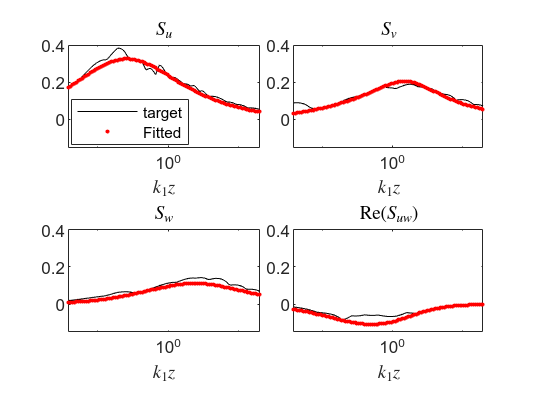

[PHI,k2,k3,k11,k2_log,k3_log] = MannTurb(alphaEps,GAMMA,L,'N1',N1,'k1min',log10(k1(1)),'k1max',log10(k1(end)));
% Compute the corresponding single point spectra
FM_fitted= squeeze(trapz(k3_log,trapz(k2_log,PHI,2),3));    
% Single point spectra is chosen
FM_fitted = FM_fitted(end-N1+1:end,:,:);
if isinf(1./max(abs(Suw(:))))
    FM_fitted(:,1,3)=0;
    FM_fitted(:,3,1)=0;
end

clf;close all;
figure
tiledlayout(2,2,"TileSpacing","tight")
nexttile
semilogx(k1.*z,k1.*Su,'k','markerfacecolor','k')
hold on;box on;
plot(k11.*z,k11'.*FM_fitted(:,1,1),'r.');
legend('target','Fitted','location','best')
title('$S_u$','interpreter','latex')
xlabel('$k_1 z$','interpreter','latex')
axis tight
ylim([-0.15,0.4])

nexttile
semilogx(k1.*z,k1.*Sv,'k','markerfacecolor','k')
hold on;box on;
plot(k11.*z,k11'.*FM_fitted(:,2,2),'r.')
title('$S_v$','interpreter','latex')
xlabel('$k_1 z$','interpreter','latex')
axis tight
ylim([-0.15,0.4])

nexttile
semilogx(k1.*z,k1.*Sw,'k','markerfacecolor','k')
hold on;box on;
plot(k11.*z,k11'.*FM_fitted(:,3,3),'r.')
title('$S_w$','interpreter','latex')
xlabel('$k_1 z$','interpreter','latex')
axis tight
ylim([-0.15,0.4])

nexttile
semilogx(k1.*z,k1.*Suw,'k','markerfacecolor','k')
hold on;box on;
plot(k11.*z,k11'.*FM_fitted(:,1,3),'r.')
title('Re$(S_{uw})$','interpreter','latex')
xlabel('$k_1 z$','interpreter','latex')
axis tight
set(gcf,'color','w');
ylim([-0.15,0.4])

## Fitting to the data Kaimal et al. [2]

### Initialisation

No blocking by the surface is modelled here. Therefore, the imaginary part of the cross power spectral density (CPSD) between the along-wind and vertical wind component is zero. 

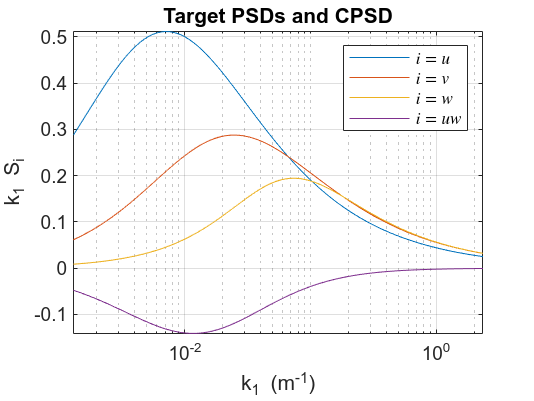

clearvars;close all;clc;
meanU = 40; % Mean wind speed (m/s)
z = 40; % altitude (m)
% z0 = 0.01; % roughness length
% kappa = 0.40; % von karman constant
% u_star = meanU*kappa./log(z./z0);
u_star = sqrt(0.86.*z^(2/3)/3.2); % cf. page 275 in ref. [3]
% u_star = 3.35; % in m/s -> Value used by Mann?
% KAIMAL SPECTRA
% frequency steps
N1=100;
% frequency vector
f = logspace(log10(1/120),log10(15),N1);
%wavenumber
k1 = 2*pi.*f./meanU;
% Reduced frequency
n = f.*z./meanU;
% Kaimal single-sided single-point power spectral densities (PSDs) and CPSD.
Su = 105.*(z./meanU)./(1+33.*n).^(5/3).*u_star.^2;
Sv = 17.*(z./meanU)./(1+9.5.*n).^(5/3).*u_star.^2;
Sw = 2.1.*(z./meanU)./(1+5.3.*n.^(5/3)).*u_star.^2;
Suw = -14.*(z./meanU)./(1+9.6.*n).^(2.4).*u_star.^2; % co-spectral density (the imagniary part of the CPSD is zero here)


clf;close all;
figure
semilogx(k1,k1.*Su ,k1,k1.*Sv ,k1,k1.*Sw,k1,k1.*Suw);
grid on
leg = legend('$i = u$','$i = v$',...
    '$i = w$','$i = uw$',...
    'location','NorthEast'); 
set(leg,'interpreter','latex')
title('Target PSDs and CPSD')
xlabel('k_{1} (m^{-1})')
ylabel('k_1 S_i');
axis tight

### Fitting procedure with three parameters

The parameters $$\alpha \epsilon^{3/2}$$ , $$\Gamma$$ and $$L$$ are estimated in the least-square sense. The parameter $$\Gamma$$ is called "GAMMA" in the function fitMann; the parameter $$\alpha \epsilon^{3/2}$$ is called "alphaEps" for the sake of simplicity and $$L$$ is simply named "L".

guess = [4,30,0.5]; % Initial guess for [GAMMA,L,alphaEps]
tic
[GAMMA,L,alphaEps] = fitMann(k1,Su,Sv,Sw,Suw,'guess',guess,'N2',50,'N3',50,'N1',30);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          4         8.18324                          14.2
     1          8        0.947483       0.834441           2.87      
     2         12        0.144158       0.247268          0.514      
     3         16       0.0576032       0.545084          0.262      
     4         20       0.0459397        0.33892          0.277      
     5         24       0.0454065      0.0657898        0.00335      

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<

toc

Elapsed time is 11.963391 seconds.


fprintf('Gamma = %2.1f \n L = %2.1f m\n alphaEps = %2.3f m^(4/3) s^(-2) \n',[GAMMA, L, alphaEps])

Gamma = 3.5 
 L = 30.8 m
 alphaEps = 0.237 m^(4/3) s^(-2) 


The parameters $$\alpha \epsilon^{3/2}$$ is here quite different from Mann [3], although the comparison between the target and the fitted PSD and CPSD is good. The parameter $$\alpha \epsilon^{3/2} = 0.86$$ isn Mann [3] is unusually large. It is possiblethat, in Mann [3], the square of the friction velocity was erroneously computed instead of the friction velocity, resulting in a very large value of $$\alpha \epsilon^{3/2}$$ . In the present case, that value $$\alpha \epsilon^{3/2} \approx 0.8$$  is, indeed, found if "u_star = (0.86.*z^(2/3)/3.2)2" is used instead of "u_star = sqrt(0.86.*z^(2/3)/3.2)". 

### Comparison between target and computed PSDs and CPSD (3-parameter fit)

The PSDs and CPSD are computed with the uniform shear model using the function MannTurb [5].

[5][ https://se.mathworks.com/matlabcentral/fileexchange/67055-uniform-shear-model-mann-1994](https://se.mathworks.com/matlabcentral/fileexchange/67055-uniform-shear-model-mann-1994)

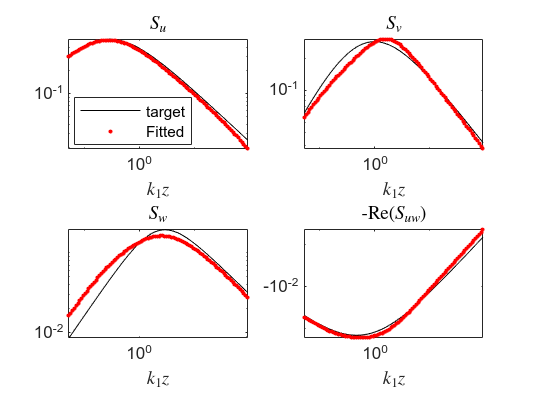

% Compute Mann spectral tensor
[PHI,k2,k3,k11,k2_log,k3_log] = MannTurb(alphaEps,GAMMA,L,'N1',N1,'k1min',log10(k1(1)),'k1max',log10(k1(end)));
% Compute the corresponding single point spectra
FM_fitted= squeeze(trapz(k3_log,trapz(k2_log,PHI,2),3));    
% Single point spectra is chosen
FM_fitted = FM_fitted(end-N1+1:end,:,:);
if isinf(1./max(abs(Suw(:))))
    FM_fitted(:,1,3)=0;
    FM_fitted(:,3,1)=0;
end

%% DATA PLOT - Result from the fitting process with 3 unknown aprameters
clf;close all;
figure
subplot(221)
hold on;box on;
plot(k1.*z,k1.*Su,'k','markerfacecolor','k')
plot(k11.*z,k11'.*FM_fitted(:,1,1),'r.');legend('target','Fitted','location','best')
set(gca,'Xscale','log','Yscale','log')
title('$S_u$','interpreter','latex')
xlabel('$k_1 z$','interpreter','latex')
axis tight

subplot(222)
hold on;box on;
plot(k1.*z,k1.*Sv,'k','markerfacecolor','k')
plot(k11.*z,k11'.*FM_fitted(:,2,2),'r.')
set(gca,'Xscale','log','Yscale','log')
title('$S_v$','interpreter','latex')
xlabel('$k_1 z$','interpreter','latex')
axis tight

subplot(223)
hold on;box on;
plot(k1.*z,k1.*Sw,'k','markerfacecolor','k')
plot(k11.*z,k11'.*FM_fitted(:,3,3),'r.')
set(gca,'Xscale','log','Yscale','log')
title('$S_w$','interpreter','latex')
xlabel('$k_1 z$','interpreter','latex')
axis tight

subplot(224)
hold on;box on;
plot(k1.*z,k1.*Suw,'k','markerfacecolor','k')
plot(k11.*z,k11'.*FM_fitted(:,1,3),'r.')
set(gca,'Xscale','log','Yscale','log')
title('-Re$(S_{uw})$','interpreter','latex')
xlabel('$k_1 z$','interpreter','latex')
axis tight

set(gcf,'color','w');

### RMSE between the Kaimal spectral model and the fitted uniform shear-model

The samve value of $$\alpha \epsilon^{3/2}$$ isused for a consistent comparison.

% L and GAMMA values found with the function fitMann
[PHI,k2,k3,k11,k2_log,k3_log] = MannTurb(alphaEps,GAMMA,L,'N1',N1,'k1min',log10(k1(1)),'k1max',log10(k1(end)));
FM_fitted1= squeeze(trapz(k3_log,trapz(k2_log,PHI,2),3));    
FM_fitted1 = FM_fitted1(end-N1+1:end,:,:);

% L and GAMMA values used by Mann [3]
[PHI,k2,k3,k11,k2_log,k3_log] = MannTurb(alphaEps,3.9,24,'N1',N1,'k1min',log10(k1(1)),'k1max',log10(k1(end)));
FM_fitted2= squeeze(trapz(k3_log,trapz(k2_log,PHI,2),3));    
FM_fitted2 = FM_fitted2(end-N1+1:end,:,:);

% RMSE value
RMSE = @(y1,y2) sqrt(nanmean((y1-y2).^2));
res=RMSE([FM_fitted1(:,1,1); FM_fitted1(:,2,2); FM_fitted1(:,3,3); FM_fitted1(:,1,1)],[Su(:);Sv(:);Sw(:);Suw(:)]);
fprintf(['RMSE with parameters from Mann [3] is ',num2str(res,3),'\n'])

RMSE with parameters from Mann [3] is 45.4


res=RMSE([FM_fitted2(:,1,1); FM_fitted2(:,2,2); FM_fitted2(:,3,3); FM_fitted2(:,1,1)],[Su(:);Sv(:);Sw(:);Suw(:)]);
fprintf(['RMSE with parameters found using fitMann is ',num2str(res,3),'\n'])

RMSE with parameters found using fitMann is 42.5


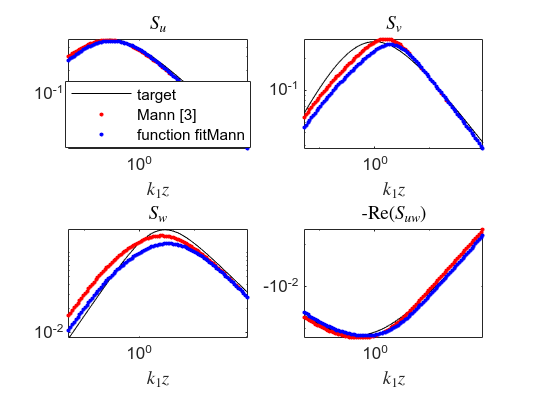


clf;close all;
figure
subplot(221)
hold on;box on;
plot(k1.*z,k1.*Su,'k','markerfacecolor','k')
plot(k11.*z,k11'.*FM_fitted1(:,1,1),'r.');
plot(k11.*z,k11'.*FM_fitted2(:,1,1),'b.');
legend('target','Mann [3]','function fitMann','location','best')

set(gca,'Xscale','log','Yscale','log')
title('$S_u$','interpreter','latex')
xlabel('$k_1 z$','interpreter','latex')
axis tight

subplot(222)
hold on;box on;
plot(k1.*z,k1.*Sv,'k','markerfacecolor','k')
plot(k11.*z,k11'.*FM_fitted1(:,2,2),'r.')
plot(k11.*z,k11'.*FM_fitted2(:,2,2),'b.');
set(gca,'Xscale','log','Yscale','log')
title('$S_v$','interpreter','latex')
xlabel('$k_1 z$','interpreter','latex')
axis tight

subplot(223)
hold on;box on;
plot(k1.*z,k1.*Sw,'k','markerfacecolor','k')
plot(k11.*z,k11'.*FM_fitted1(:,3,3),'r.')
plot(k11.*z,k11'.*FM_fitted2(:,3,3),'b.');
set(gca,'Xscale','log','Yscale','log')
title('$S_w$','interpreter','latex')
xlabel('$k_1 z$','interpreter','latex')
axis tight

subplot(224)
hold on;box on;
plot(k1.*z,k1.*Suw,'k','markerfacecolor','k')
plot(k11.*z,k11'.*FM_fitted1(:,1,3),'r.')
plot(k11.*z,k11'.*FM_fitted2(:,1,3),'b.');
set(gca,'Xscale','log','Yscale','log')
title('-Re$(S_{uw})$','interpreter','latex')
xlabel('$k_1 z$','interpreter','latex')
axis tight

set(gcf,'color','w');

The value of the fitted parameters $$\Gamma$$, and $$L$$ are slightly different than in Mann [3]. However, for the same value of $$\alpha \epsilon^{3/2}$$,  the computation of the total Root-mean square error show a lower value in the present case than in Mann [3]. In conclusion, for the range of frequencies consdiered and in the case of the Kaimal spectrum, the fitting algorithm is here more performant than the one used by Mann [3] in terms of RMSE. If a different frequency range is used, different parameters will be found.

### Fitting procedure with two parameters

The parameters $$\Gamma$$ and $$L$$ are estimated in the least-square sense while $$\alpha \epsilon^{3/2}$$  is already known. 

guess = [4,30]; % Initial guess for [GAMMA,L]
alphaEps1 = alphaEps; % in m^(4/3)s^(-2)
tic
[GAMMA,L] = fitMann(k1,Su,Sv,Sw,Suw,'guess',guess,'alphaEps',alphaEps1,'N2',50,'N3',50,'N1',30);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          3        0.120077                         0.686
     1          6       0.0476899       0.198979         0.0663      
     2          9       0.0454456       0.225898         0.0812      
     3         12       0.0454045      0.0140508        0.00625      

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


toc

Elapsed time is 6.281123 seconds.


fprintf('Gamma = %2.1f \n L = %2.1f m\n alphaEps = %2.3f m^(4/3) s^(-2) \n',[GAMMA, L, alphaEps])

Gamma = 3.5 
 L = 30.9 m
 alphaEps = 0.237 m^(4/3) s^(-2) 


### Comparison between target and computed PSDs and CPSD (2-parameter fit)

The PSDs and CPSD are computed with the uniform shear model using the function MannTurb [5].

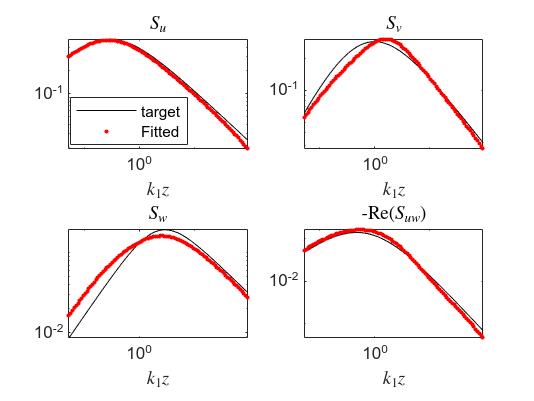

% Compute Mann spectral tensor
[PHI,k2,k3,k11,k2_log,k3_log] = MannTurb(alphaEps1,GAMMA,L,'N1',N1,'k1min',log10(k1(1)),'k1max',log10(k1(end)));
% Compute the corresponding single point spectra
FM_fitted= squeeze(trapz(k3_log,trapz(k2_log,PHI,2),3));    
% Single point spectra is chosen
FM_fitted = FM_fitted(end-N1+1:end,:,:);
if isinf(1./max(abs(Suw(:))))
    FM_fitted(:,1,3)=0;
    FM_fitted(:,3,1)=0;
end

%% DATA PLOT - Result from the fitting process with 3 unknown aprameters
clf;close all;
figure
subplot(221)
hold on;box on;
plot(k1.*z,k1.*Su,'k','markerfacecolor','k')
plot(k11.*z,k11'.*FM_fitted(:,1,1),'r.');legend('target','Fitted','location','best')
set(gca,'Xscale','log','Yscale','log')
title('$S_u$','interpreter','latex')
xlabel('$k_1 z$','interpreter','latex')
axis tight

subplot(222)
hold on;box on;
plot(k1.*z,k1.*Sv,'k','markerfacecolor','k')
plot(k11.*z,k11'.*FM_fitted(:,2,2),'r.')
set(gca,'Xscale','log','Yscale','log')
title('$S_v$','interpreter','latex')
xlabel('$k_1 z$','interpreter','latex')
axis tight

subplot(223)
hold on;box on;
plot(k1.*z,k1.*Sw,'k','markerfacecolor','k')
plot(k11.*z,k11'.*FM_fitted(:,3,3),'r.')
set(gca,'Xscale','log','Yscale','log')
title('$S_w$','interpreter','latex')
xlabel('$k_1 z$','interpreter','latex')
axis tight

subplot(224)
hold on;box on;
semilogx(k1.*z,-k1.*Suw,'k','markerfacecolor','k')
plot(k11.*z,-k11'.*FM_fitted(:,1,3),'r.')
set(gca,'Xscale','log','Yscale','log')
title('-Re$(S_{uw})$','interpreter','latex')
xlabel('$k_1 z$','interpreter','latex')
axis tight

set(gcf,'color','w');